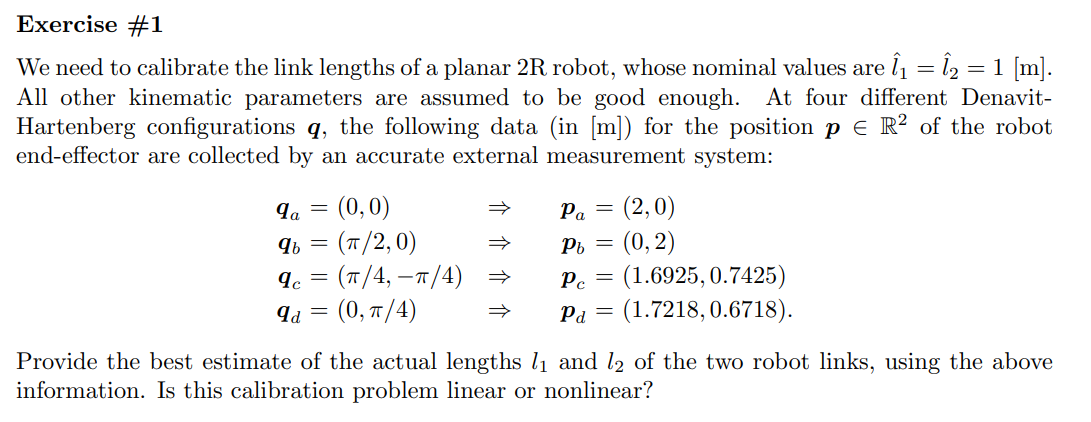

clc
clear all
close all

% addpath("Functions/Robotics1") % Linux
% addpath("Functions/Robotics2") % Linux
addpath("Functions\Robotics1") % Windows
addpath("Functions\Robotics2") % Windows

% se da trovare con DH la posizione data da 0A1*1A2*...*[0 0 0 1]'
syms l1 l2 alpha1 alpha2 d1 d2 q1 q2 real


f = [l1*cos(q1) + l2*cos(q1+q2);
     l1*sin(q1) + l2*sin(q1+q2)]

$$f = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$


% posizioni misurate nelle varie configurazioni del tipo [x1 y1 x2 y2 ...]'
r_bar = [2 0 0 2 1.6925 0.7425 1.7218 0.6718]'

r_bar =     2.0000
         0
         0
    2.0000
    1.6925
    0.7425
    1.7218
    0.6718



% valori di q nelle varie configurazioni
q1_bar = [0 pi/2 pi/4 0]';
q2_bar = [0 0 -pi/4 pi/4]';

% valori iniziali di a (da calibrare!) in generale anche altri valori
phi_nom = [1 1]';

% variabili dh che vogliamo calibrare, in questo caso solo a
a = [l1 l2];
% alpha = [alpha1 alpha2];
% d = [d1 d2];
% q = [q1 q2]

% jacobiane rispetto al valore da calibrare (per espansione di Taylor)
dfda = jacobian(f, a)

$$dfda = \left(\begin{array}{cc} \cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}\right) & \sin\left(q_{1}+q_{2}\right) \end{array}\right)$$

% dfdalpha = jacobian(f, alpha)
% dfdd = jacobian(f, d)
% dfdtheta = jacobian(f, q)
Phi = [dfda];
% Phi = [dfda dfdalpha dfdd dfdtheta] % in generale

% creazione regressor matrix e calcolo di r_nom
Phi_bar = [];
r_nom_bar = [];
for i = 1:length(q1_bar)
    Phi_bar = [Phi_bar; 
           subs(Phi, {q1, q2}, {q1_bar(i), q2_bar(i)})];
    r_nom_bar = [r_nom_bar; 
             subs(f, {q1, q2, l1, l2}, {q1_bar(i), q2_bar(i), phi_nom(1), phi_nom(2)})];
end

% quanto si discostano le posizioni nominali da quelle effetivamente
% misurate. r_mis - calcolate (f(q_mis))
delta_r_bar = vpa(r_bar - r_nom_bar, 5)

$$delta\_r = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ -0.014607\\ 0.035393\\ 0.014693\\ -0.035307 \end{array}\right)$$



% risolvo problema linare per calcolare delta_phi
delta_phi = vpa(pinv(Phi_bar)*delta_r_bar, 5)

$$delta\_phi = \left(\begin{array}{c} 0.05001\\ -0.049982 \end{array}\right)$$


% aggiorno valori da calibrare
phi_primo = vpa(phi_nom + delta_phi, 5)

$$phi\_primo = \left(\begin{array}{c} 1.05\\ 0.95002 \end{array}\right)$$


% potenzialmente necessario ripetere operazioni (se non lineare)
% utilizzando phi_primo al posto di phi_nom
% phi_nom = phi_primo

% è lineare in a, perché compare l1 e l2 in modo lineare in f











